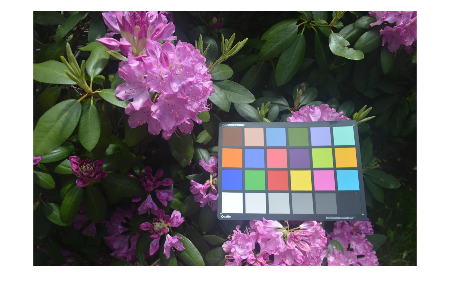

pic = imread("colorCheckerTestImage.jpg");
imshow(pic);

sigma=0.3;J=4;iter=1;lambda=1;q=0.2;epsilon=0.01;c=q*epsilon^(q/2-1);

pic_GAT = ...
GenAnscombe_forward(pic, sigma);

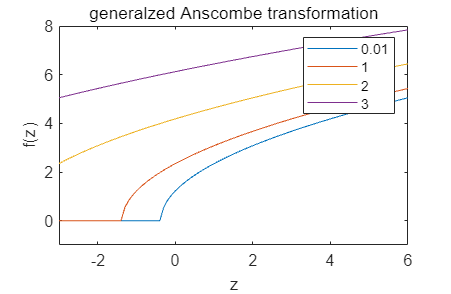

z=-100:0.1:100;
gatz1=GenAnscombe_forward(z, 0.01);
gatz2=GenAnscombe_forward(z, 1);
gatz3=GenAnscombe_forward(z, 2);
gatz4=GenAnscombe_forward(z, 3);
plot(z,gatz1);hold on;
axis([-3,6,-1,8]);
xlabel('z');ylabel('f(z)');
title('generalzed Anscombe transformation');
plot(z,gatz2);hold on;
plot(z,gatz3);hold on;plot(z,gatz4);hold on;
legend('0.01','1','2','3');hold off;

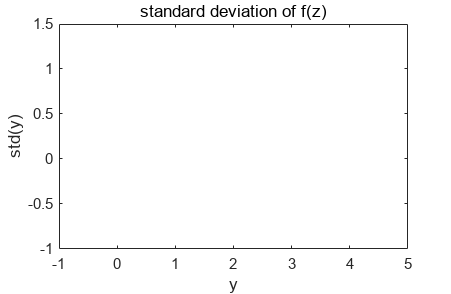

y=0:0.1:5;
plot(y,std(gatz1));hold on;
axis([-1,5,-1,1.5]);
xlabel('y');ylabel('std(y)');
title('standard deviation of f(z)');
plot(y,std(gatz2));hold on;
plot(y,std(gatz3));hold on;
plot(y,std(gatz4));hold off;